# NLS evolution an unbalanced star graph

Evolves a solution to the NLS equation on an "unbalanced" star graph as discussed in Kairzhan et al "Drift of Spectrally Stable Shifted States on Star Graphs," SIAM J. Appl. Dyn. Sys., 2018.

The momentum is not conserved, but the mass and energy are.

## Set up the graph structure and coordinates of the problem

By default, the discretization type is uniform but you may choose it to be Chebyshev for the time evolution. You can also set other properties such as the number of discretization points per edge.

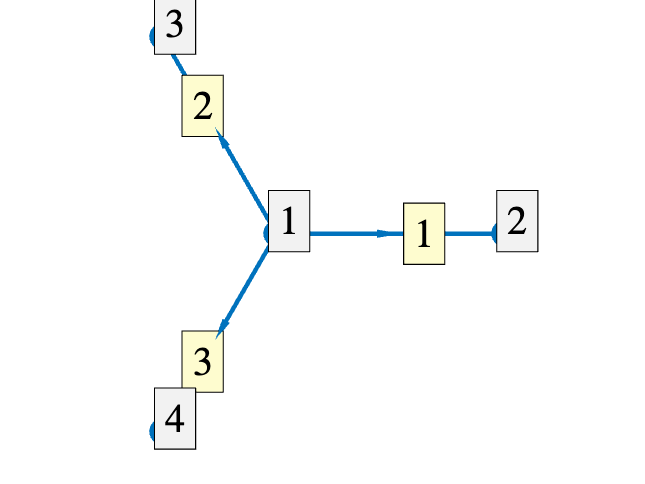

robinCoeff = [0 NaN NaN NaN];
LVec = 30;
weight = [1 1 1];
G = quantumGraphFromTemplate('star','LVec',LVec,'discretization','Uniform','robinCoeff',robinCoeff,'weight',weight);
G.plot('layout')

## Define and plot the initial conditions 

Define the cubic nonlinear Schrodinger time equation on G.

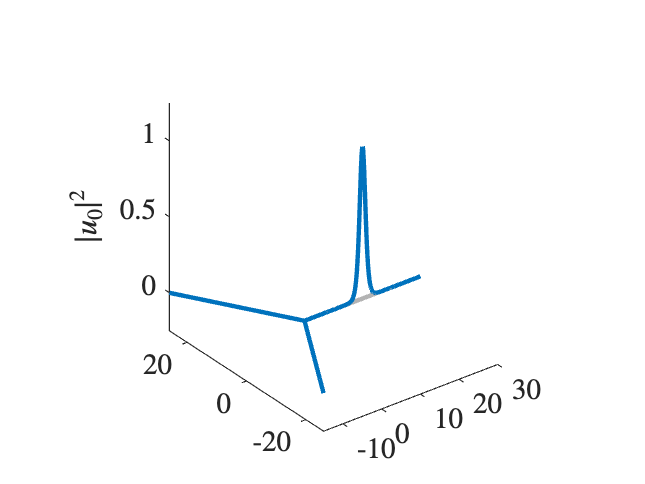

v0 = -1;     % Initial velocity
init1 = @(x) exp(-1i*x*v0).*sech(x-LVec/2);   
init2 = @(x)  exp(1i*x*v0).*sech(x+LVec/2);   
u0 = G.applyFunctionsToAllEdges({init1,init2,init2});
G.plot(abs(u0).^2);
zlabel('$|u_0|^2$')

## Function Definition and Time evolution


$$f(t,u) = \mu \triangle u + F(u)$$


mu = -1i; 
F =@(z) -2i * z.^2 .* conj(z);
tFinal = 15;
dtPrint=0.5;
dt = 0.01;
nSkip= dtPrint/dt;
tic;
[t,u] = G.qgdeSDIRK443(mu,F,tFinal,u0,dt,'nSkip',nSkip);
elapsed_time=toc

elapsed_time = 7.4249

## Plotting the solution

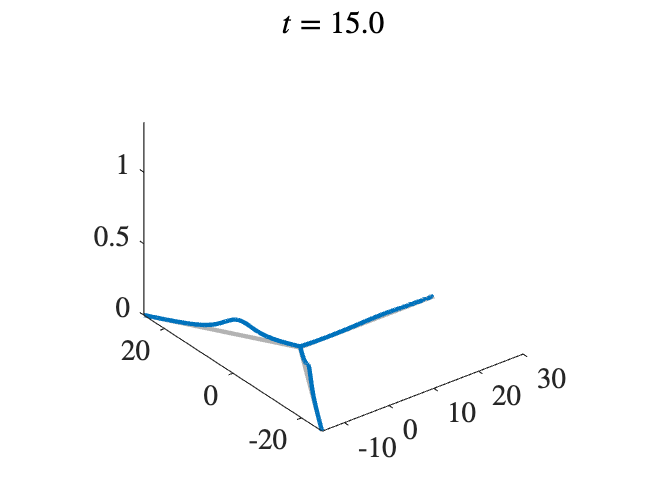

%G.animatePDESolution(u,t);

## Error Analysis

Check for conservation of energy, mass and momentum.

nt = length(t);
energyVec = zeros(nt,1);
massVec = zeros(nt,1);
momentumVec= zeros(nt,1);

fcns.F=@(u)abs(u).^4; % The quartic term in the energy functional

for j=1:nt
    uj = u(:,j);
    energyVec(j)=G.energyNLS(uj,fcns);
    massVec(j) = G.norm(uj)^2;
    momentumVec(j) = G.momentumNLS(uj);
end

#### Plot the relative drift in the energy

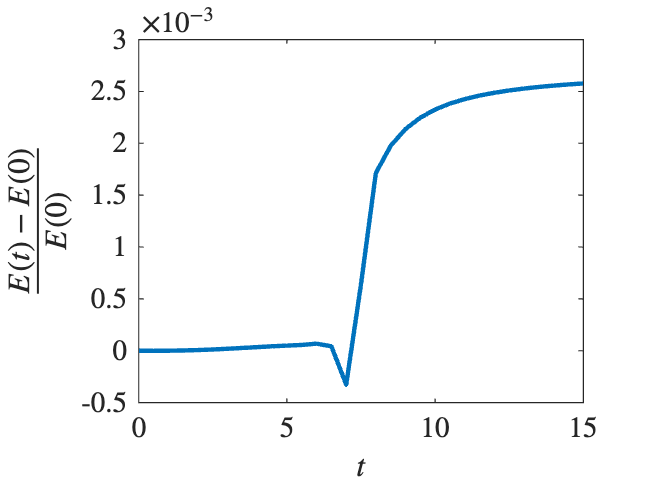

energyDiff=(energyVec-energyVec(1))/energyVec(1);
plot(t,energyDiff)
xlabel('$t$')
ylabel('$\frac{E(t)-E(0)}{E(0)}$')

#### Plot the relative drift in the mass

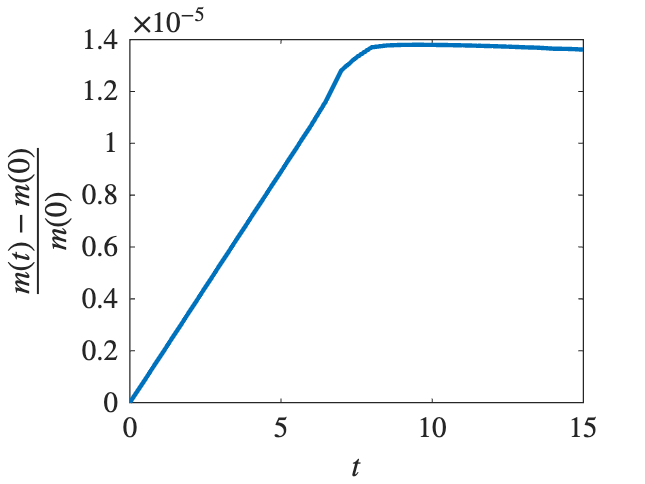

massDiff = (massVec-massVec(1))/massVec(1);
plot(t,massDiff)
xlabel('$t$')
ylabel('$\frac{m(t)-m(0)}{m(0)}$')

#### Plot the relative drift in the momentum

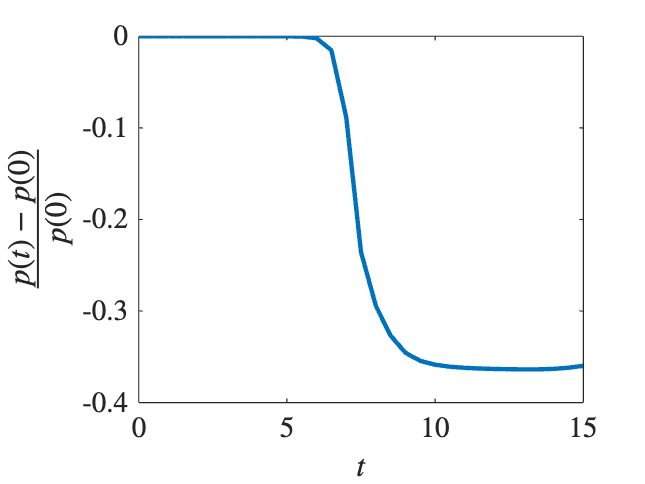

momentumDiff = (momentumVec-momentumVec(1))/momentumVec(1);
plot(t,momentumDiff)
xlabel('$t$')
ylabel('$\frac{p(t)-p(0)}{p(0)}$')

## Convergence test

We will double the temporal resolution twice and interpolate the solution to the central vertex.

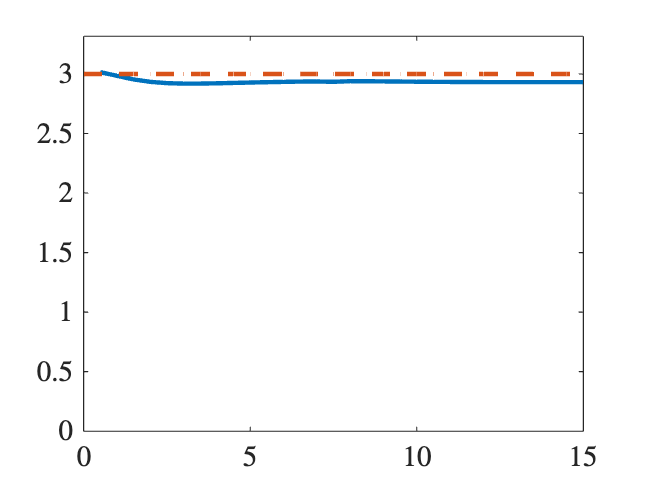

% nT=length(t);
% errorArray=zeros(nT,2);
% for j=1:2
%     dt = dt/2;
%     nSkip= tPrint/dt;
%     [t,u2] = G.qgdeSDIRK443(mu,F,tFinal,u0,dt,'nSkip',nSkip);
%     for k=1:length(t)
%         errorArray(k,j)=G.norm(u(:,k)-u2(:,k));
%     end
%     u=u2;
% end
% errorRatio=errorArray(:,1)./errorArray(:,2);
% plot(t,log2(errorRatio),t,3*ones(size(t)),'--'); axis([0 tFinal 0 1.1*max(log2(errorRatio))])